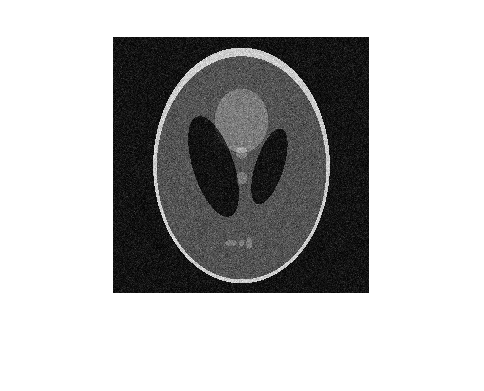

%PART 5
clc;
clear all;
close all;
f1 = imread('shepp256.png');
f1 = double(f1);
F1=fftshift(fft2(f1));
n3 =normrnd(0, 5000, 256, 256) + 1i*normrnd(0, 5000, 256, 256);
N3=fftshift(fft2(n3));


F1BIVARIATE=F1 + n3;
f1bivariate=ifft2(ifftshift(F1BIVARIATE));
im2=abs(f1bivariate);
%im=uint8(im);
figure(20);
imshow(abs(f1bivariate),[]);

imwrite(abs(f1bivariate),'phantombivariate.jpg');


%choose pixels

%FOR TISSUE 1

windo=15;
signal=zeros(windo,windo);
background=zeros(windo,windo);
waitfor(msgbox('Choose a Tissue 1 Pixel'));
figure(21);
set(gcf,'Units','normalized','outerposition',[0 0 1 1]);
[c1,r1,~]=impixel(im2,[]);
close figure 21
waitfor(msgbox('Choose a Background Pixel'));
figure(22);
set(gcf,'Units','normalized','outerposition',[0 0 1 1]);
[c2,r2,~]=impixel(im2,[]);
close figure 22

signal=im2(r1:r1+windo-1,c1:c1+windo-1);
background=im2(r2:r2+windo-1,c2:c2+windo-1);
signal= double(signal);
background= double(background);
signal=reshape(signal,1,numel(signal));
background=reshape(background,1,numel(background));
signalmean=mean(signal);
backgroundmean=mean(background);
signalsd=std(signal);
backgroundsd=std(background);
SNR1=(signalmean/backgroundsd);

%for tissue 2
windo=15;
signal=zeros(windo,windo);
background=zeros(windo,windo);
waitfor(msgbox('Choose a Tissue 2 Pixel'));
figure(23);
set(gcf,'Units','normalized','outerposition',[0 0 1 1]);
[c1,r1,~]=impixel(im2,[]);
close figure 23
waitfor(msgbox('Choose a Background Pixel'));
figure(24);
set(gcf,'Units','normalized','outerposition',[0 0 1 1]);
[c2,r2,~]=impixel(im2,[]);
close figure 24

signal1=im2(r1:r1+windo-1,c1:c1+windo-1);
background=im2(r2:r2+windo-1,c2:c2+windo-1);

Index in position 2 exceeds array bounds. Index must not exceed 256.

signal1= double(signal1);
background= double(background);
signal1=reshape(signal1,1,numel(signal1));
background=reshape(background,1,numel(background));
signal1mean=mean(signal1);
backgroundmean=mean(background);
signal1sd=std(signal1);
backgroundsd=std(background);
SNR2=(signal1mean/backgroundsd);

%find CNR

CNR=(signalmean-signal1mean)/(backgroundsd)